syms w u(t) x(t) r(t) h(t) y(t)
u(t) = heaviside(t);
x(t) = (0.5*t).*(u(t)-u(t-2)); 
h(t) =  (u(t-1)-u(t-3))

$$h(t) = \mathrm{heaviside}\left(t-1\right)-\mathrm{heaviside}\left(t-3\right)$$

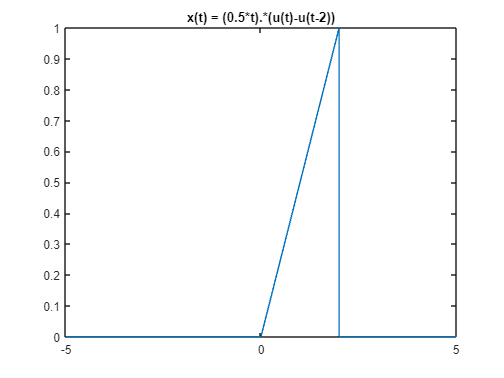

y(t) = int(x(w)*h(t-w), w, -inf, inf);
fplot(x(t))
title('x(t) = (0.5*t).*(u(t)-u(t-2))')

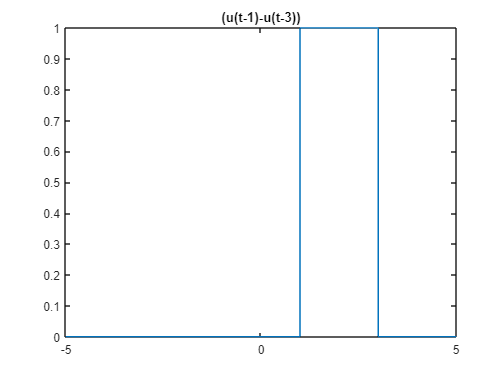

fplot(h(t))
title('(u(t-1)-u(t-3))')

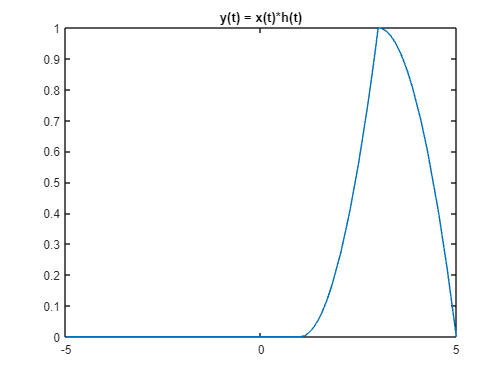

fplot(y(t))
title('y(t) = x(t)*h(t)')